# Radar Signal Processing Verification

This script has been written to confirm that the signal processing component of a radar is working as anticipated

## Initialize the simulator

clear;
simulator = Simulator_revB();
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_highBW.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_highvres.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_lowBW.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_sensing_system.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/X310_params_100MHzBW.json";
file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/realistic_params.json";
simulator.load_params_from_JSON(file_path);


%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 10.76 MHz/us
	 Idle Time: 			 7.95 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.42 us
	 ADC Samples: 			 256 
	 ADC Sample Rate: 		 7.17 MSps
	 Ramp End Time: 		 42.12 us
	 Chirp Tx Bandwidth: 		 453.21 MHz
	 Chirp Sampling Bandwidth: 	 384.18 MHz
	 ADC Sampling Period: 		 35.70 us
	 Chirp Cycle Time: 		 50.07 us
	 Chirp Wavelength: 		 3.89 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 6.41 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 99.88 m
	 Range Resolution 		 0.39 m
	 Max Velocity 			 19.44 m/s
	 Velocity Resolution 		 0.30 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 458.88 MHz
	 Downsampling factor 		 64
	 Sweep time 			 42.12 us
	 Samples per chirp 		 22976.00 


## Initialize the Target

simulator.load_target_realistic();

## Run the simulation

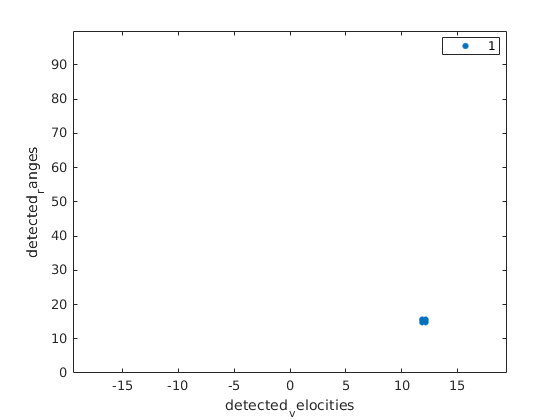

%specify the number of frames and chirps to compute
frames_to_compute = 100;

%specify whether or not to record a move of the range-doppler plot
record_movie = true;
simulator.Victim.Radar_Signal_Processor.configure_movie_capture(frames_to_compute,record_movie);

%pre-compute the victim's chirps
simulator.Victim.precompute_radar_chirps();

%run the simulation (without an attacker for now)
simulator.run_simulation_no_attack(frames_to_compute);

## Results

%get the estimated ranges and velocities
simulator.Victim.Radar_Signal_Processor.range_estimates

ans =    54.6944       NaN       NaN       NaN       NaN
   54.4746       NaN       NaN       NaN       NaN
   54.2051       NaN       NaN       NaN       NaN
   53.8998       NaN       NaN       NaN       NaN
   53.0471       NaN       NaN       NaN       NaN
   52.7740       NaN       NaN       NaN       NaN
   52.5524       NaN       NaN       NaN       NaN
   52.2852       NaN       NaN       NaN       NaN
   51.4570       NaN       NaN       NaN       NaN
   51.1261       NaN       NaN       NaN       NaN


simulator.Victim.Radar_Signal_Processor.velocity_estimates

ans =    11.9975       NaN       NaN       NaN       NaN
   11.9967       NaN       NaN       NaN       NaN
   11.9971       NaN       NaN       NaN       NaN
   11.9809       NaN       NaN       NaN       NaN
   11.9925       NaN       NaN       NaN       NaN
   11.9988       NaN       NaN       NaN       NaN
   11.9991       NaN       NaN       NaN       NaN
   11.9942       NaN       NaN       NaN       NaN
   11.9726       NaN       NaN       NaN       NaN
   11.9963       NaN       NaN       NaN       NaN


%play the movie for the range doppler
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_range_doppler_movie();
end

%play the movie for the clusters
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_clustering_movie()
end